# Import Data

load('.\R15N111_Raw.mat')   % wave，横轴是采样点数，采样率是 24414.0625Hz
% 声音刺激是多个 50ms 的短纯音
load('.\R15N111_Stimulus.mat')    % freqs, levels, sti_onset，短纯音的频率、强度和刺激起始时刻

# 画出原始信号

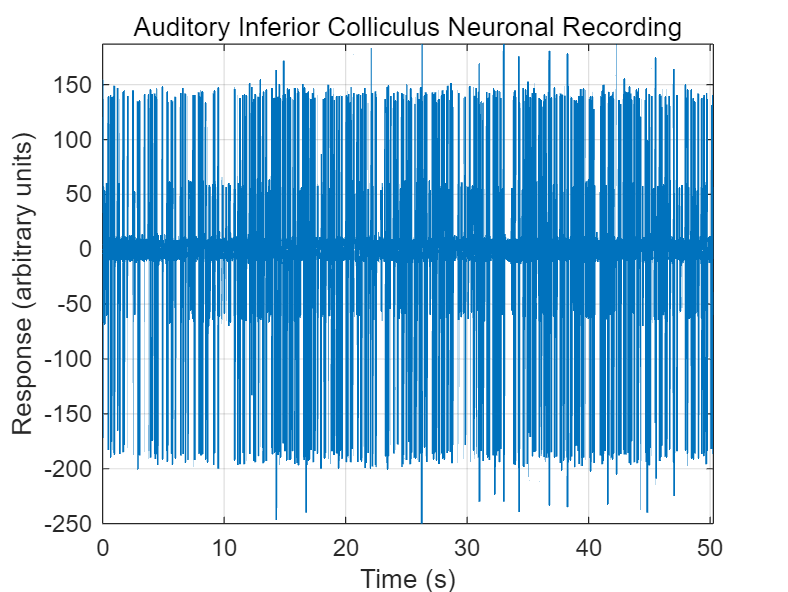

Fs = 24414.0625;            % 采样率 (Hz)
data = wave;                % 原始数据
num_samples = length(data); % 总采样点数

% 创建时间轴（秒），注意把采样点转换成时间
time_axis = (0:num_samples-1) / Fs;

figure;
plot(time_axis, data, 'Color', [0 0.4470 0.7410], 'LineWidth', 0.8);

xlabel('Time (s)');
ylabel('Response (arbitrary units)');
title('Auditory Inferior Colliculus Neuronal Recording');

grid on;

axis tight;


disp(['Recording duration: ', num2str(num_samples/Fs), ' seconds']);

Recording duration: 50.2687 seconds


disp(['Data range: ', num2str(min(data)), ' to ', num2str(max(data))]);

Data range: -250 to 187


# Check Raw

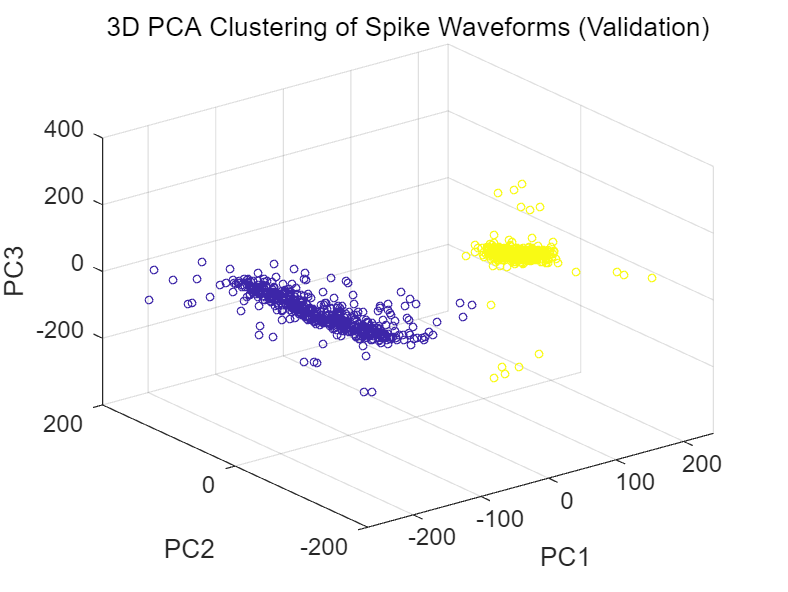

load('.\R15N111_Spikes.mat')  % unit1, unit2，两个神经细胞的放电序列时刻
%% Waveform Validation
pre = 20;                % Pre-peak samples
post = 30;               % Post-peak samples
Fs = 24414.0625;         % Sampling rate (Hz)

% 转换数据格式
wave_double = double(wave);

% 提取unit1对应的原始波形
spike_indices1 = round(unit1 * Fs) + 1;  % 转换为采样点索引
valid_idx1 = (spike_indices1 > pre) & (spike_indices1 <= length(wave)-post);
spike_indices1 = spike_indices1(valid_idx1);

waveforms1 = zeros(length(spike_indices1), pre+post);
for i = 1:length(spike_indices1)
    idx = spike_indices1(i);
    waveforms1(i,:) = wave_double(idx-pre : idx+post-1);
end

% 提取unit2对应的原始波形
spike_indices2 = round(unit2 * Fs) + 1;
valid_idx2 = (spike_indices2 > pre) & (spike_indices2 <= length(wave)-post);
spike_indices2 = spike_indices2(valid_idx2);

waveforms2 = zeros(length(spike_indices2), pre+post);
for i = 1:length(spike_indices2)
    idx = spike_indices2(i);
    waveforms2(i,:) = wave_double(idx-pre : idx+post-1);
end

% 验证降维
waveforms_ori = [waveforms1; waveforms2];
[~, score] = pca(waveforms_ori);
features = score(:,1:3); % 取前3个主成分

% K-means聚类
rng('default'); % 保证结果可重复
[idx, ~] = kmeans(features, 2, 'Replicates', 5);

% 可视化聚类结果
figure;
scatter3(features(:,1), features(:,2), features(:,3), 10, idx);
title('3D PCA Clustering of Spike Waveforms (Validation)');
xlabel('PC1'); ylabel('PC2'); zlabel('PC3');

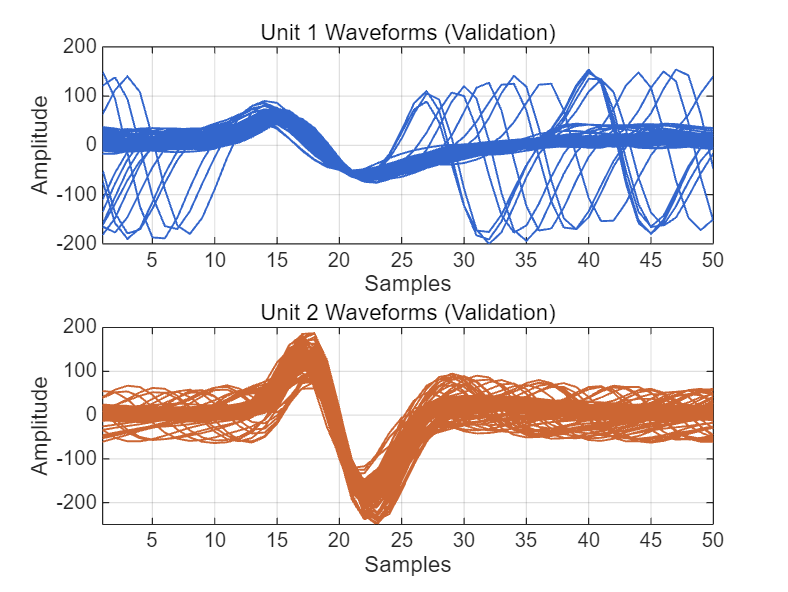


%% 绘制验证波形
figure;
subplot(2,1,1);
plot(waveforms1', 'Color', [0.2 0.4 0.8], 'LineWidth', 0.8);
xlim([1 50]);
title('Unit 1 Waveforms (Validation)');
xlabel('Samples');
ylabel('Amplitude');
grid on;

subplot(2,1,2);
plot(waveforms2', 'Color', [0.8 0.4 0.2], 'LineWidth', 0.8);
xlim([1 50]);
title('Unit 2 Waveforms (Validation)');
xlabel('Samples');
ylabel('Amplitude');
grid on;


% 显示统计信息
disp('Validation Results:');

Validation Results:


disp(['Unit 1 validated waveforms: ', num2str(size(waveforms1,1))]);

Unit 1 validated waveforms: 503


disp(['Unit 2 validated waveforms: ', num2str(size(waveforms2,1))]);

Unit 2 validated waveforms: 532


disp(['Total waveform duration: ', num2str((pre+post+1)/Fs*1000), ' ms']);

Total waveform duration: 2.089 ms


# Spike Sorting

进行Spike Sorting，分离出两个神经细胞的放电序列时刻（time stamp）

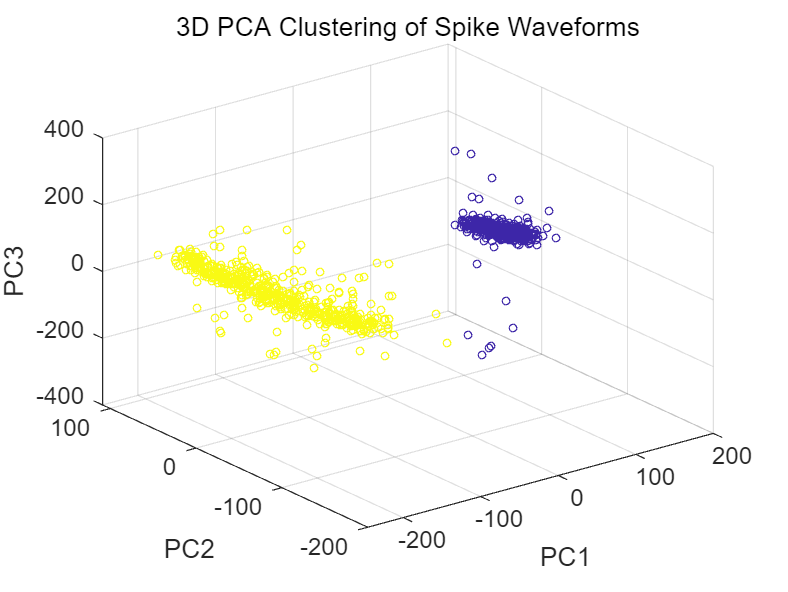

pre = 20;                % 峰前采样点数
post = 30;              % 峰后采样点数
threshold_multiplier = 7;% 阈值倍数
min_refractory = 0.0006;  % 不应期（秒）

% 转换数据格式
wave_double = double(wave);

% Calculate threshold using MAD method
mad_val = mad(wave_double);
threshold = threshold_multiplier * mad_val;

% Spike检测
min_peak_distance = round(min_refractory * Fs);
[~, spike_locs] = findpeaks(-wave_double,...    % negative
    'MinPeakHeight', threshold,...
    'MinPeakDistance', min_peak_distance);

% 提取有效Spike位置
valid_idx = (spike_locs > pre) & (spike_locs <= length(wave_double)-post);
spike_locs = spike_locs(valid_idx);

% 提取波形数据
waveforms = zeros(length(spike_locs), pre+post);
for i = 1:length(spike_locs)
    range = (spike_locs(i)-pre):(spike_locs(i)+post-1);
    waveforms(i,:) = wave_double(range);
end

% PCA降维
[~, score] = pca(waveforms);
features = score(:,1:3); % 取前3个主成分

% K-means聚类
rng('default'); % 保证结果可重复
[idx, ~] = kmeans(features, 2, 'Replicates', 5);

% 转换时间戳并分配结果
timestamps = (spike_locs - 1) / Fs; % 转换为秒
unit1 = timestamps(idx == 1)';
unit2 = timestamps(idx == 2)';

% 可视化聚类结果
figure;
scatter3(features(:,1), features(:,2), features(:,3), 10, idx);
title('3D PCA Clustering of Spike Waveforms');
xlabel('PC1'); ylabel('PC2'); zlabel('PC3');

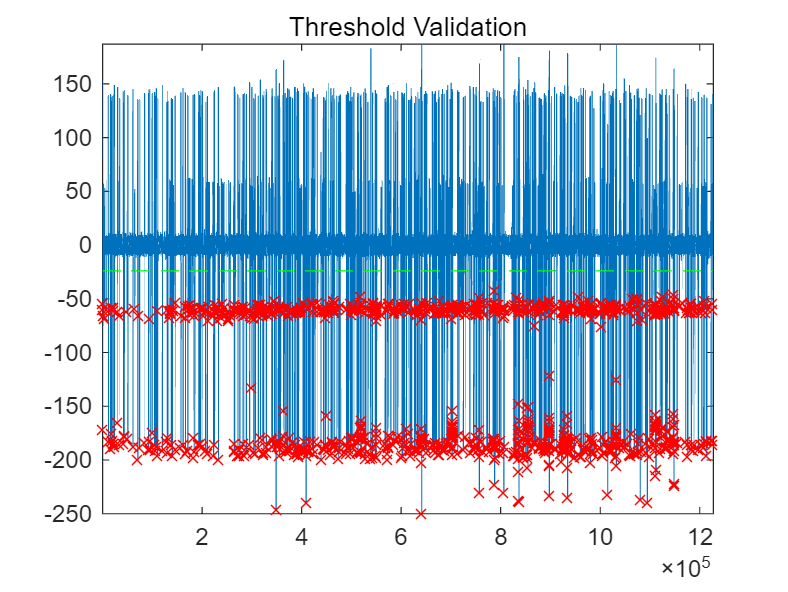


% 阈值验证
figure; 
plot(wave_double); 
hold on; 
plot(spike_locs, wave_double(spike_locs), 'rx');
plot([1,length(wave_double)], [-threshold, -threshold], 'g--');
axis tight;
title('Threshold Validation');

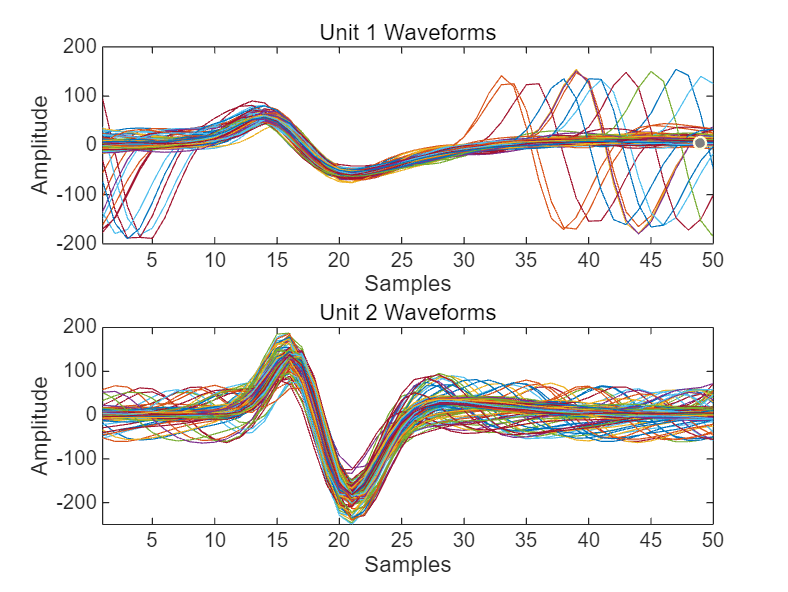


% 绘制典型波形
figure;
subplot(2,1,1);
plot(waveforms(idx==1,:)');
xlim([1 50])
title('Unit 1 Waveforms');
xlabel('Samples');
ylabel('Amplitude');
subplot(2,1,2);
plot(waveforms(idx==2,:)');
xlim([1 50])
title('Unit 2 Waveforms');
xlabel('Samples');
ylabel('Amplitude');

disp(['Unit1检测到', num2str(length(unit1)), '个Spike']);

Unit1检测到505个Spike


disp(['Unit2检测到', num2str(length(unit2)), '个Spike']);

Unit2检测到532个Spike


# 找到最优刺激频率和强度，绘制FRA

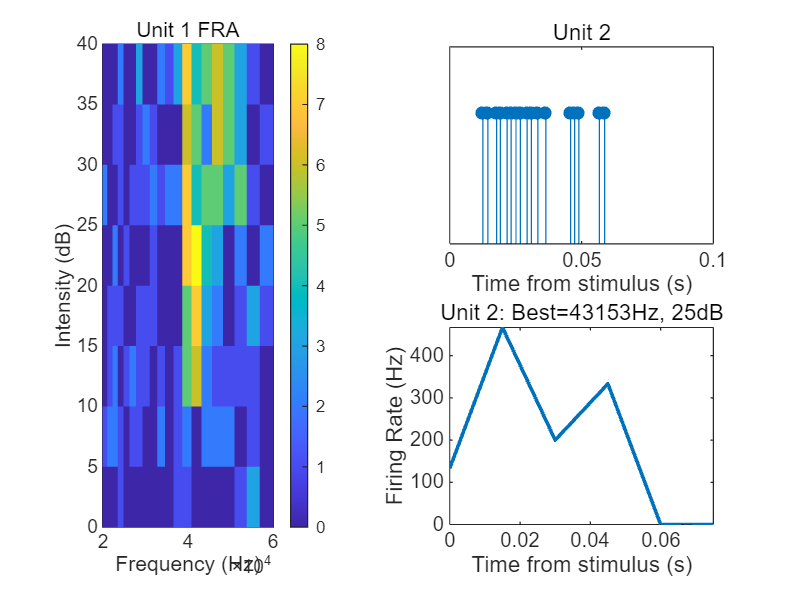

%% 1. 数据预处理
stim_duration = 0.05;  % 刺激持续时间50ms
response_window = [0 0.1];  % 分析窗口0-100ms
bin_size = 0.015;  % 15ms时间分档

%% 2. 创建刺激参数矩阵
[unique_freqs, ~, freq_idx] = unique(freqs);
[unique_levels, ~, level_idx] = unique(levels);
[FreqGrid, LevelGrid] = meshgrid(unique_freqs, unique_levels);
response_matrix1 = zeros(length(unique_levels), length(unique_freqs));
response_matrix2 = response_matrix1;

%% 3. 计算每个刺激条件下的响应次数
for i = 1:length(sti_onset)
    % 当前刺激参数
    current_freq = freq_idx(i);
    current_level = level_idx(i);
    stim_start = sti_onset(i);
    stim_end = stim_start + response_window(2);
    
    % 统计unit1的响应
    spikes_in_window1 = unit1 > stim_start & unit1 < stim_end;
    response_matrix1(current_level, current_freq) = ...
        response_matrix1(current_level, current_freq) + sum(spikes_in_window1);
    
    % 统计unit2的响应
    spikes_in_window2 = unit2 > stim_start & unit2 < stim_end;
    response_matrix2(current_level, current_freq) = ...
        response_matrix2(current_level, current_freq) + sum(spikes_in_window2);
end

%% 4. 寻找最优刺激参数
% 对unit1
[max_resp1, max_idx1] = max(response_matrix1(:));
[opt_level1, opt_freq1] = ind2sub(size(response_matrix1), max_idx1);
opt_freq1 = unique_freqs(opt_freq1);
opt_level1 = unique_levels(opt_level1);

% 对unit2
[max_resp2, max_idx2] = max(response_matrix2(:));
[opt_level2, opt_freq2] = ind2sub(size(response_matrix2), max_idx2);
opt_freq2 = unique_freqs(opt_freq2);
opt_level2 = unique_levels(opt_level2);

%% 5. 提取最优条件下的刺激事件
% unit1最优条件
valid_trials1 = (freqs == opt_freq1) & (levels == opt_level1);
selected_onsets1 = sti_onset(valid_trials1);

% unit2最优条件
valid_trials2 = (freqs == opt_freq2) & (levels == opt_level2);
selected_onsets2 = sti_onset(valid_trials2);

%% 6. 计算PSTH（0-100ms时间窗）Peri-Stimulus Time Histogram 刺激时间直方图
% 计算时间轴
time_bins = response_window(1):bin_size:response_window(2);
time_bins = time_bins(1:end-1);  % 调整最后一个bin的边界

% 对unit1
psth1 = zeros(size(time_bins));
for t = 1:length(selected_onsets1)
    stim_time = selected_onsets1(t);
    spikes_aligned = unit1 - stim_time;
    spikes_aligned = spikes_aligned(spikes_aligned >= response_window(1) & ...
                                    spikes_aligned < response_window(2));
    psth1 = psth1 + histcounts(spikes_aligned, 'BinEdges', [time_bins, response_window(2)]);
end
psth1 = psth1 / length(selected_onsets1) / bin_size;  % 转换为放电率（Hz）

% 对unit2
psth2 = zeros(size(time_bins));
for t = 1:length(selected_onsets2)
    stim_time = selected_onsets2(t);
    spikes_aligned = unit2 - stim_time;
    spikes_aligned = spikes_aligned(spikes_aligned >= response_window(1) & ...
                                    spikes_aligned < response_window(2));
    psth2 = psth2 + histcounts(spikes_aligned, 'BinEdges', [time_bins, response_window(2)]);
end
psth2 = psth2 / length(selected_onsets2) / bin_size;

%% 7. 可视化结果
% Unit 1 热图
subplot(1,2,1)
% 绘制伪彩色图
h = pcolor(FreqGrid, LevelGrid, response_matrix1);
set(h, 'EdgeColor', 'none');  % 去除网格线
axis xy;  % y轴0点在底部
xlabel('Frequency (Hz)');
ylabel('Intensity (dB)');
title('Unit 1 FRA');
colorbar;

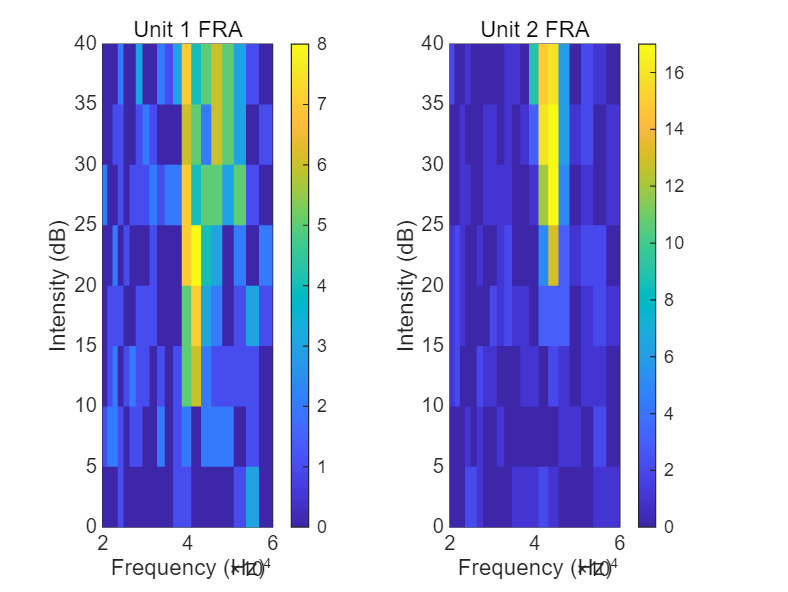


% Unit 2 热图（同理）
subplot(1,2,2)
h = pcolor(FreqGrid, LevelGrid, response_matrix2);
set(h, 'EdgeColor', 'none');  % 去除网格线
axis xy;  % y轴0点在底部
xlabel('Frequency (Hz)');
ylabel('Intensity (dB)');
title('Unit 2 FRA');
colorbar;

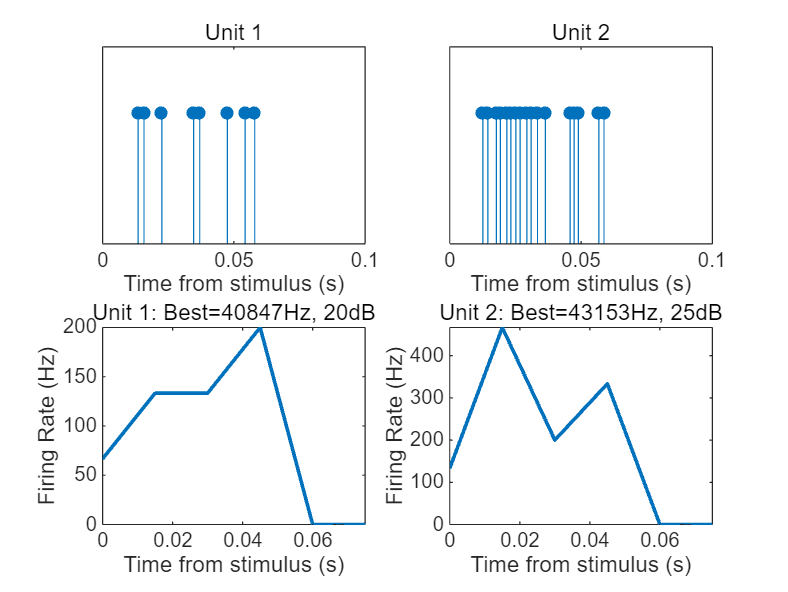


% 查看原始放电序列
figure;
% 对unit1
stim_time = selected_onsets1;
spikes_in_window = unit1(unit1 >= stim_time & unit1 < stim_time + response_window(2));
aligned_spikes = spikes_in_window - stim_time;  % 对齐到刺激起始时刻

subplot(2, 2, 1);
stem(aligned_spikes, ones(size(aligned_spikes)), 'filled', 'MarkerSize', 5);
xlim(response_window);  % 固定x轴范围为0-100ms
ylim([0, 1.5]);  % 固定y轴范围
yticks([]);  % 隐藏y轴刻度
xlabel('Time from stimulus (s)');
title('Unit 1');

% 对unit2
stim_time = selected_onsets2;
spikes_in_window = unit2(unit2 >= stim_time & unit2 < stim_time + response_window(2));
aligned_spikes = spikes_in_window - stim_time;  % 对齐到刺激起始时刻

subplot(2, 2, 2);
stem(aligned_spikes, ones(size(aligned_spikes)), 'filled', 'MarkerSize', 5);
xlim(response_window);  % 固定x轴范围为0-100ms
ylim([0, 1.5]);  % 固定y轴范围
yticks([]);  % 隐藏y轴刻度
xlabel('Time from stimulus (s)');
title('Unit 2');

% 绘制PSTH
subplot(2,2,3);
plot(time_bins, psth1, 'LineWidth', 1.5);
xlabel('Time from stimulus (s)'), ylabel('Firing Rate (Hz)');
title(sprintf('Unit 1: Best=%.0fHz, %.0fdB', opt_freq1, opt_level1));

subplot(2,2,4);
plot(time_bins, psth2, 'LineWidth', 1.5);
xlabel('Time from stimulus (s)'), ylabel('Firing Rate (Hz)');
title(sprintf('Unit 2: Best=%.0fHz, %.0fdB', opt_freq2, opt_level2));


% 显示统计信息
disp('Unit 1 Optimal Parameters:');

Unit 1 Optimal Parameters:


disp(['Frequency: ', num2str(opt_freq1), 'Hz']);

Frequency: 40846.8711Hz


disp(['Intensity: ', num2str(opt_level1), 'dB']);

Intensity: 20dB


disp(['Total trials: ', num2str(sum(valid_trials1))]);

Total trials: 1



disp('Unit 2 Optimal Parameters:');

Unit 2 Optimal Parameters:


disp(['Frequency: ', num2str(opt_freq2), 'Hz']);

Frequency: 43153.3906Hz


disp(['Intensity: ', num2str(opt_level2), 'dB']);

Intensity: 25dB


disp(['Total trials: ', num2str(sum(valid_trials2))]);

Total trials: 1


# 根据FRA确定特征频率（CF）

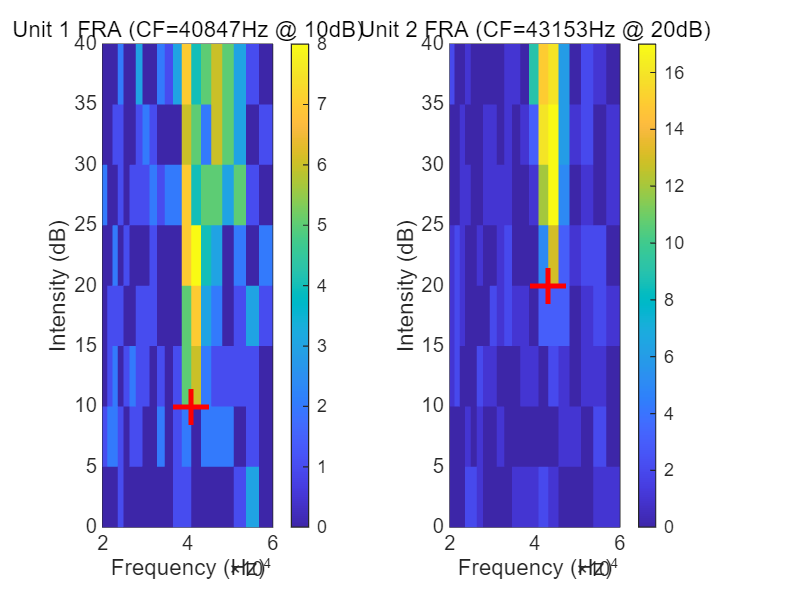

%% 确定特征频率（CF）
% 参数设置
response_threshold = 5;  % 最低有效响应次数阈值

% 对Unit 1
% 找到每个强度下的最佳频率
[~, max_freq_idx1] = max(response_matrix1, [], 2);  % 每行最大值的列索引
best_freqs1 = unique_freqs(max_freq_idx1);

% 提取每行最大值对应的响应次数
max_responses1 = response_matrix1(sub2ind(size(response_matrix1), (1:size(response_matrix1, 1))', max_freq_idx1));

% 寻找CF（最低强度下能引发响应的频率）
valid_levels1 = unique_levels(max_responses1 >= response_threshold);
if ~isempty(valid_levels1)
    cf_level1 = min(valid_levels1);  % 最低有效强度
    cf_idx1 = find(unique_levels == cf_level1);
    cf1 = best_freqs1(cf_idx1);
else
    % 如果最低强度无响应，选择最稳定响应的频率
    [mode_freq, ~] = mode(best_freqs1);
    cf1 = mode_freq;
    cf_level1 = 'N/A (no reliable threshold)';
end

% 对Unit 2
[~, max_freq_idx2] = max(response_matrix2, [], 2);
best_freqs2 = unique_freqs(max_freq_idx2);

% 提取每行最大值对应的响应次数
max_responses2 = response_matrix2(sub2ind(size(response_matrix2), (1:size(response_matrix2, 1))', max_freq_idx2));

valid_levels2 = unique_levels(max_responses2 >= response_threshold);
if ~isempty(valid_levels2)
    cf_level2 = min(valid_levels2);
    cf_idx2 = find(unique_levels == cf_level2);
    cf2 = best_freqs2(cf_idx2);
else
    [mode_freq, ~] = mode(best_freqs2);
    cf2 = mode_freq;
    cf_level2 = 'N/A (no reliable threshold)';
end

%% 可视化CF
figure;
subplot(1,2,1)
h = pcolor(FreqGrid, LevelGrid, response_matrix1);
set(h, 'EdgeColor', 'none');  % 去除网格线
axis xy;  % y轴0点在底部
xlabel('Frequency (Hz)');
ylabel('Intensity (dB)');
title(sprintf('Unit 1 FRA (CF=%.0fHz @ %.0fdB)', cf1, cf_level1));
colorbar;
hold on;
plot(cf1, cf_level1, 'r+', 'MarkerSize', 15, 'LineWidth', 2);  % 标记CF

subplot(1,2,2)
h = pcolor(FreqGrid, LevelGrid, response_matrix2);
set(h, 'EdgeColor', 'none');  % 去除网格线
axis xy;  % y轴0点在底部
xlabel('Frequency (Hz)');
ylabel('Intensity (dB)');
title(sprintf('Unit 2 FRA (CF=%.0fHz @ %.0fdB)', cf2, cf_level2));
colorbar;
hold on;
plot(cf2, cf_level2, 'r+', 'MarkerSize', 15, 'LineWidth', 2);  % 标记CF

# 统计ISI

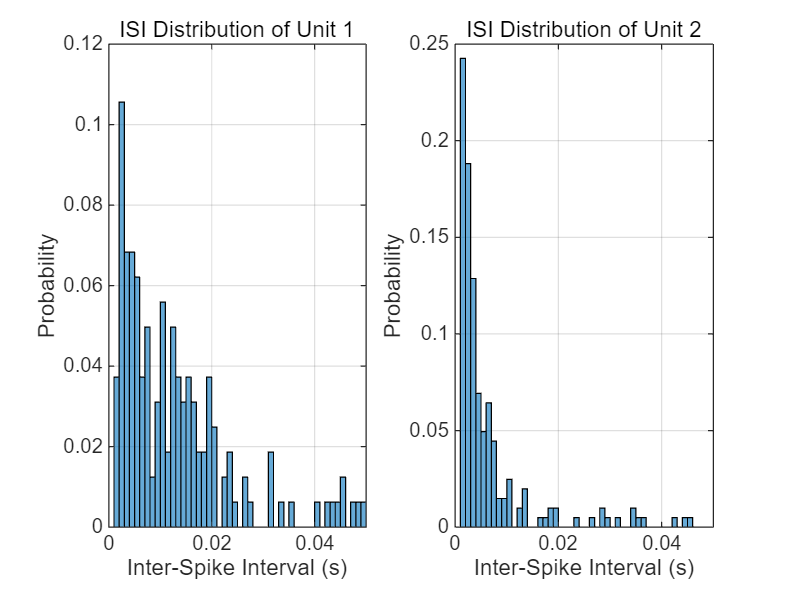

%% 1. 提取所有刺激条件下的ISI数据
% 参数设置
response_window = [0 0.1];  % 0-100ms时间窗

% 初始化存储ISI的cell数组
isi_unit1 = {};
isi_unit2 = {};

% 遍历所有刺激事件
for i = 1:length(sti_onset)
    stim_time = sti_onset(i);
    
    % 提取unit1的ISI
    spikes_unit1 = unit1(unit1 >= stim_time & unit1 < stim_time + response_window(2));
    if length(spikes_unit1) >= 2
        isi = diff(spikes_unit1);
        isi_unit1{end+1} = isi;
    end
    
    % 提取unit2的ISI
    spikes_unit2 = unit2(unit2 >= stim_time & unit2 < stim_time + response_window(2));
    if length(spikes_unit2) >= 2
        isi = diff(spikes_unit2);
        isi_unit2{end+1} = isi;
    end
end

% 合并所有ISI数据
all_isi_unit1 = [isi_unit1{:}];
all_isi_unit2 = [isi_unit2{:}];

%% 2. 绘制ISI分布直方图
% 设置直方图参数
bin_edges = 0:0.001:0.05;  % 1ms分档，范围0-50ms
xlim_range = [0 0.05];     % 显示0-50ms范围

% 绘制unit1的ISI直方图
subplot(1,2,1);
histogram(all_isi_unit1, bin_edges, 'Normalization', 'probability');
xlabel('Inter-Spike Interval (s)');
ylabel('Probability');
title('ISI Distribution of Unit 1');
xlim(xlim_range);
grid on;

% 绘制unit2的ISI直方图
subplot(1,2,2);
histogram(all_isi_unit2, bin_edges, 'Normalization', 'probability');
xlabel('Inter-Spike Interval (s)');
ylabel('Probability');
title('ISI Distribution of Unit 2');
xlim(xlim_range);
grid on;


% 显示统计信息
disp('Unit 1 ISI Statistics:');

Unit 1 ISI Statistics:


disp(['Total spikes: ', num2str(sum(cellfun(@length, isi_unit1))+cellfun(@length, isi_unit1))]);

Total spikes: 163  162  162  162  162  162  162  162  162  162  162  165  166  162  162  165  163  167  163  164  167  168  163  162  162  162  164  162  163  162  162  165  165  162  167  165  166  166  165  162  163  162  165  164  167  165  162  163  163  166  165  162  163  165  163  166  163  166  162  166


disp(['Mean ISI: ', num2str(mean(all_isi_unit1)), ' s']);

Mean ISI: 0.014026 s


disp(['Median ISI: ', num2str(median(all_isi_unit1)), ' s']);

Median ISI: 0.010486 s



disp('Unit 2 ISI Statistics:');

Unit 2 ISI Statistics:


disp(['Total spikes: ', num2str(sum(cellfun(@length, isi_unit2))+cellfun(@length, isi_unit2))]);

Total spikes: 203  203  203  203  203  203  203  204  203  204  203  203  204  203  204  204  214  203  206  203  204  203  203  213  218  206  207  204  217  218  203  216  203  210  217  203  207  203  203  211  203  218  205  203  215


disp(['Mean ISI: ', num2str(mean(all_isi_unit2)), ' s']);

Mean ISI: 0.0088954 s


disp(['Median ISI: ', num2str(median(all_isi_unit2)), ' s']);

Median ISI: 0.0035635 s


# 自定义FRA

%% 1. 绘制可交互的FRA热图并创建mask
% Unit 1 FRA
figure;
h = pcolor(FreqGrid, LevelGrid, response_matrix1);
set(h, 'EdgeColor', 'none');
axis xy;
xlabel('Frequency (Hz)');
ylabel('Intensity (dB)');
title('Unit1 Best Region');
colorbar;

% 交互式选择
hold on;
points = [];
disp('开始绘制区域：左键单击添加点，右键单击删除最后一点，双击完成绘制');

开始绘制区域：左键单击添加点，右键单击删除最后一点，双击完成绘制


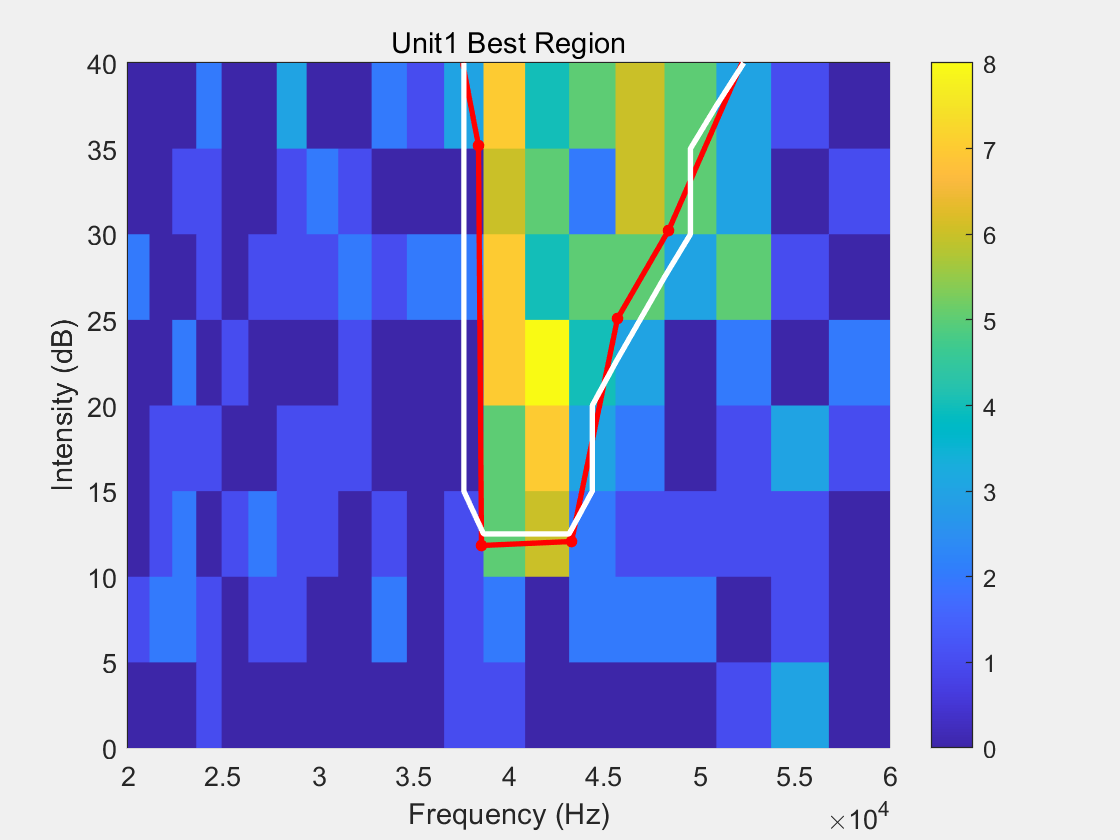

while true
    [x, y] = ginput(1);
    if isempty(x)  % 双击结束
        break;
    end
    points = [points; x y];
    plot(points(:,1), points(:,2), 'r.-', 'MarkerSize', 15, 'LineWidth', 2);
end

% 创建mask
vertices = points;
mask_unit1 = inpolygon(FreqGrid(:), LevelGrid(:), vertices(:,1), vertices(:,2));
mask_unit1 = reshape(mask_unit1, size(FreqGrid));

% 可视化最终区域
contour(FreqGrid, LevelGrid, mask_unit1, [0.5 0.5], 'LineWidth', 2, 'LineColor', 'w');

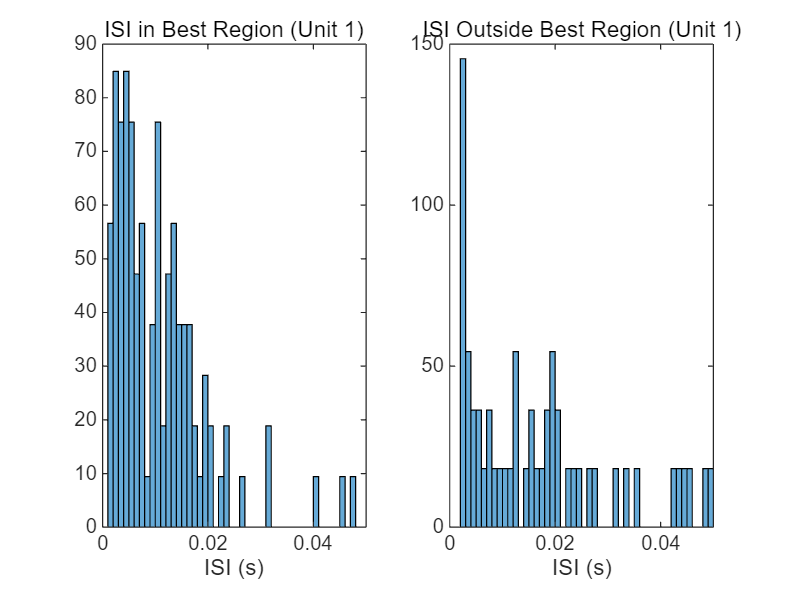


%% 2. 提取区域内/外的ISI数据（使用cell数组避免维度错误）
isi_in_unit1 = {};
isi_out_unit1 = {};

for i = 1:length(sti_onset)
    current_freq = freqs(i);
    current_level = levels(i);
    
    % 使用网格匹配
    [freq_idx, ~] = find(unique_freqs == current_freq);
    [level_idx, ~] = find(unique_levels == current_level);
    in_region = mask_unit1(level_idx, freq_idx);
    
    % 提取ISI（使用cell数组存储）
    stim_time = sti_onset(i);
    spikes = unit1(unit1 >= stim_time & unit1 < stim_time + 0.1);
    
    if ~isempty(spikes) && length(spikes) >= 2
        isi = diff(spikes);
        if in_region
            isi_in_unit1{end+1} = isi;  % 使用cell存储
        else
            isi_out_unit1{end+1} = isi;
        end
    end
end

% 合并ISI数据
isi_in_unit1 = [isi_in_unit1{:}];
isi_out_unit1 = [isi_out_unit1{:}];

%% 3. 绘制ISI对比直方图
figure;
subplot(1,2,1);
histogram(isi_in_unit1, 'BinWidth', 0.001, 'Normalization', 'pdf');
title('ISI in Best Region (Unit 1)');
xlabel('ISI (s)');
xlim([0 0.05]);

subplot(1,2,2);
histogram(isi_out_unit1, 'BinWidth', 0.001, 'Normalization', 'pdf');
title('ISI Outside Best Region (Unit 1)');
xlabel('ISI (s)');
xlim([0 0.05]);


%% 1. 绘制可交互的FRA热图并创建mask (Unit 2)
% Unit 2 FRA
figure;
h = pcolor(FreqGrid, LevelGrid, response_matrix2);
set(h, 'EdgeColor', 'none');
axis xy;
xlabel('Frequency (Hz)');
ylabel('Intensity (dB)');
title('Unit2 Best Region');
colorbar;

% 交互式选择
hold on;
points = [];
disp('开始绘制区域：左键单击添加点，右键单击删除最后一点，双击完成绘制');

开始绘制区域：左键单击添加点，右键单击删除最后一点，双击完成绘制


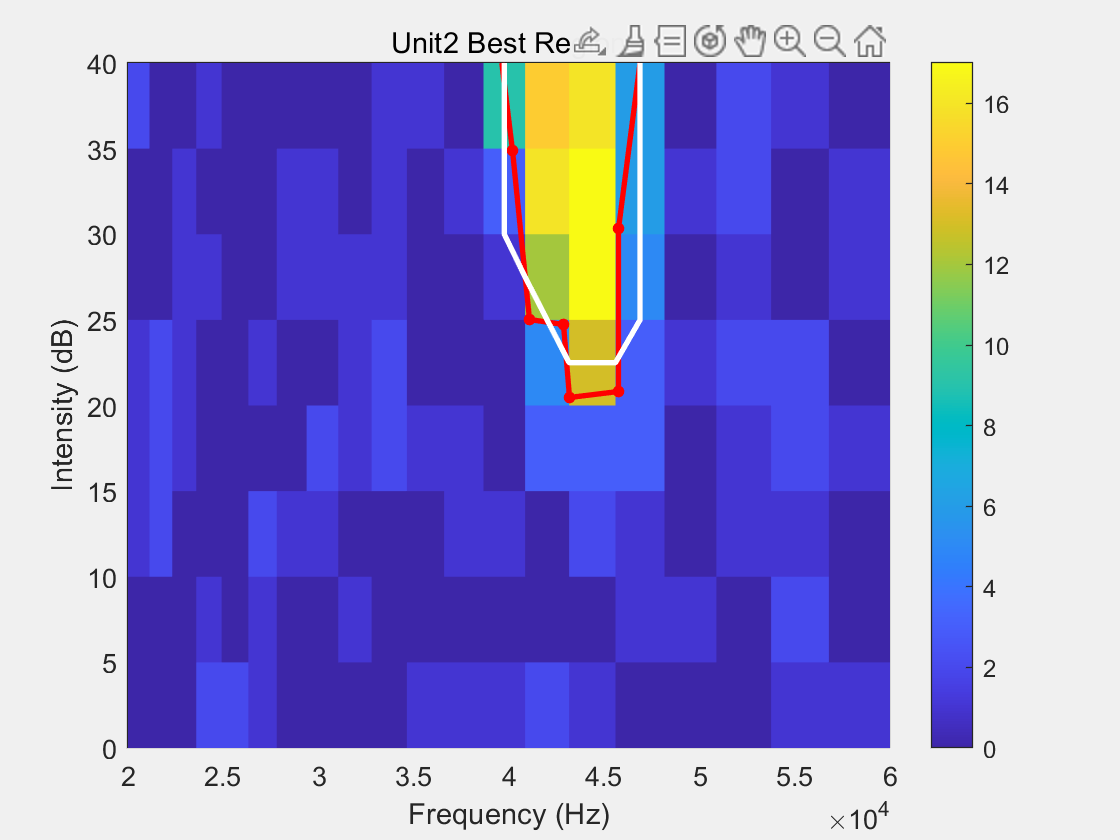

while true
    [x, y] = ginput(1);
    if isempty(x)  % 双击结束
        break;
    end
    points = [points; x y];
    plot(points(:,1), points(:,2), 'r.-', 'MarkerSize', 15, 'LineWidth', 2);
end

% 创建mask
vertices = points;
mask_unit2 = inpolygon(FreqGrid(:), LevelGrid(:), vertices(:,1), vertices(:,2));
mask_unit2 = reshape(mask_unit2, size(FreqGrid));

% 可视化最终区域
contour(FreqGrid, LevelGrid, mask_unit2, [0.5 0.5], 'LineWidth', 2, 'LineColor', 'w');

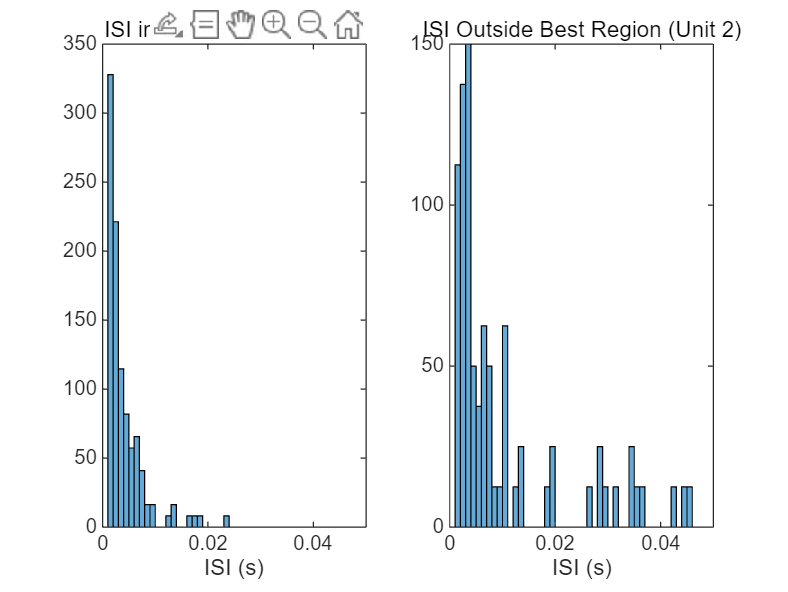


%% 2. 提取区域内/外的ISI数据（使用cell数组避免维度错误）
isi_in_unit2 = {};
isi_out_unit2 = {};

for i = 1:length(sti_onset)
    current_freq = freqs(i);
    current_level = levels(i);
    
    % 使用网格匹配
    [freq_idx, ~] = find(unique_freqs == current_freq);
    [level_idx, ~] = find(unique_levels == current_level);
    in_region = mask_unit2(level_idx, freq_idx);
    
    % 提取ISI（使用cell数组存储）
    stim_time = sti_onset(i);
    spikes = unit2(unit2 >= stim_time & unit2 < stim_time + 0.1);
    
    if ~isempty(spikes) && length(spikes) >= 2
        isi = diff(spikes);
        if in_region
            isi_in_unit2{end+1} = isi;  % 使用cell存储
        else
            isi_out_unit2{end+1} = isi;
        end
    end
end

% 合并ISI数据
isi_in_unit2 = [isi_in_unit2{:}];
isi_out_unit2 = [isi_out_unit2{:}];

%% 3. 绘制ISI对比直方图 (Unit 2)
figure;
subplot(1,2,1);
histogram(isi_in_unit2, 'BinWidth', 0.001, 'Normalization', 'pdf');
title('ISI in Best Region (Unit 2)');
xlabel('ISI (s)');
xlim([0 0.05]);

subplot(1,2,2);
histogram(isi_out_unit2, 'BinWidth', 0.001, 'Normalization', 'pdf');
title('ISI Outside Best Region (Unit 2)');
xlabel('ISI (s)');
xlim([0 0.05]);

# 结果检验

% 双样本 Kolmogorov-Smirnov (KS) 检验
% Unit 1: 区域内 vs 区域外
[h_unit1, p_unit1, ksstat_unit1] = kstest2(isi_in_unit1, isi_out_unit1);
fprintf('--- Unit 1 KS Test Results ---\n');

--- Unit 1 KS Test Results ---


if h_unit1
    fprintf('Null hypothesis rejected (p = %.4f): ISI distributions in and out of the best region are significantly different.\n', p_unit1);
else
    fprintf('Failed to reject null hypothesis (p = %.4f): No significant difference between ISI distributions.\n', p_unit1);
end

Null hypothesis rejected (p = 0.0008): ISI distributions in and out of the best region are significantly different.


fprintf('KS statistic: %.4f\n\n', ksstat_unit1);

KS statistic: 0.3225




% Unit 2: 区域内 vs 区域外
[h_unit2, p_unit2, ksstat_unit2] = kstest2(isi_in_unit2, isi_out_unit2);
fprintf('--- Unit 2 KS Test Results ---\n');

--- Unit 2 KS Test Results ---


if h_unit2
    fprintf('Null hypothesis rejected (p = %.4f): ISI distributions in and out of the best region are significantly different.\n', p_unit2);
else
    fprintf('Failed to reject null hypothesis (p = %.4f): No significant difference between ISI distributions.\n', p_unit2);
end

Null hypothesis rejected (p = 0.0000): ISI distributions in and out of the best region are significantly different.


fprintf('KS statistic: %.4f\n\n', ksstat_unit2);

KS statistic: 0.3484




% 比较Unit 1和Unit 2的区域内ISI分布
[h_between_units, p_between_units, ksstat_between_units] = kstest2(isi_in_unit1, isi_in_unit2);
fprintf('--- Comparison Between Unit 1 and Unit 2 (Best Region) ---\n');

--- Comparison Between Unit 1 and Unit 2 (Best Region) ---


if h_between_units
    fprintf('Null hypothesis rejected (p = %.4f): ISI distributions of Unit 1 and Unit 2 in the best region are significantly different.\n', p_between_units);
else
    fprintf('Failed to reject null hypothesis (p = %.4f): No significant difference between ISI distributions.\n', p_between_units);
end

Null hypothesis rejected (p = 0.0000): ISI distributions of Unit 1 and Unit 2 in the best region are significantly different.


fprintf('KS statistic: %.4f\n\n', ksstat_between_units);

KS statistic: 0.4555

